# **Tugas Pendahuluan Day 3 - Shift 2**

`Nama : Tesalonika Permatasari Hutapea`

`NIM  : 10121052`

## Nomor 1

Terdapat beberapa teknik interpolasi yang sudah dipelajari di kelas Matematika Numerik. Sekarang, mari kita mempelajari teknik interpolasi lain yang juga bisa digunakan, yaitu **"Natural Cubic Spline Interpolation"**.

Misalkan terdapat kumpulan titik pada bidang, yaitu $\left(x_0 ,y_0 \right),\left(x_1 ,y_1 \right),\left(x_2 ,y_2 \right),\ldotp \ldotp \ldotp ,\left(x_n ,y_n \right)$. Natural Cubic Spline menginterpolasi titik-titik tersebut menggunakan Piecewise Function yang didefinisikan sebagai


$${\mathit{\mathbf{S}}}_{\mathit{\mathbf{i}}} \left(\mathit{\mathbf{x}}\right)={a_i \left(x-x_i \right)}^3 +b_i {\left(x-x_i \right)}^2 +c_i \left(x-x_i \right)+d_i ,x_i \le x\le x_{i+1} ,\;i=0,1,2,\ldotp \ldotp \ldotp ,n-1\;\;\ldotp \ldotp \ldotp \left(1\right)$$


Agar fungsi tersebut kontinu di seluruh titik yang dilewati, terdapat beberapa kondisi yang harus dipenuhi untuk $S_i \left(x\right),{S_i }^{\prime } \left(x\right),{{S_i }^{\prime } }^{\prime } \left(x\right)$ di setiap titik. Melalui beberapa penurunan, didapatkan bahwa


$$a_i =\frac{\left(b_{i+1} -b_i \right)}{3h_i },i=0,1,2,\ldotp \ldotp \ldotp ,n-1\;\ldotp \ldotp \ldotp \left(2\right)$$



$$b_{i-1} h_{i-1} +2b_i \left(h_{i-1} +h_i \right)+b_{i+1} h_i =\frac{3}{h_i }\left(y_{i+1} -y_i \right)-\frac{3}{h_i }\left(y_i -y_{i-1} \right),i=1,2,\ldotp \ldotp \ldotp ,n-1\;\ldotp \ldotp \ldotp \left(3\right)$$



$$c_i =\frac{\left(y_{i+1} -y_i \right)}{h_i }-a_i h_i^2 -b_i h_i ,i=0,1,2,\ldotp \ldotp \ldotp ,n-1\;\ldotp \ldotp \ldotp \left(4\right)$$



$$d_i =y_i ,i=0,1,2,\ldotp \ldotp \ldotp ,n-1\;\ldotp \ldotp \ldotp \left(5\right)$$


dengan $h_i =x_{i+1} -x_i$ dan didefinisikan untuk **Natural Cubic Spline Interpolation **$b_0 =0=b_n$.

Di soal ini, kita akan mencoba untuk melakukan interpolasi terhadap fungsi $p\left(x\right)=e^{\sin \left(x\right)}$ pada selang $\left\lbrack -3,3\right\rbrack$ dengan $\Delta x=0\ldotp 1$.

## Nomor 1A

Perhatikan persamaan (4)! Tuliskan rumus $c_i$ tersebut dalam variabel $b_i$ dan $b_{i+1}$!

Jawab :


$$c_i \;=\frac{\left(y_{i+1} -y_i \right)}{h_i }-a_i h_i^2 -b_i h_i \;=\frac{y_i -y_{i-1} }{h_i }+\frac{\left(b_{i-1} +2b_i \right)}{3}h_i \;,\;i=0,1,2,\ldotp \ldotp \ldotp ,n-1$$


## Nomor 1B

Pencarian koefisien-koefisien dari Piecewise Function yang dimaksud membutuhkan nilai $b_i$. Perhatikan bahwa persamaan (3) membentuk suatu Sistem Persamaan Linear (SPL) $\textrm{Ab}=t$ untuk mencari $b_i$ dengan $i=1,2,\ldotp \ldotp \ldotp ,n-1$. Tuliskan SPL yang dimaksud!

Jawab :


$$\left\lbrack \begin{array}{ccccccc}
2\times \left(h_0 +h_1 \right) & h_1  & 0 & 0 & 0 & \ldotp \ldotp \ldotp  & 0\\
h_1  & 2\times \left(h_1 +h_2 \right) & h_2  & 0 & 0 & \ldotp \ldotp  & 0\\
0 & h_2  & 2\times \left(h_2 +h_3 \right) & h_3  & 0 & \ldotp \ldotp \ldotp  & 0\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \;\\
0 & 0 & \ldotp \ldotp \ldotp  & 0 & h_{n-3}  & 2\times \left(h_{n-3} +h_{n-2} \right) & h_{n-2} \\
0 & 0 & 0 & 0 & 0 & h_{n-2}  & 2\times \left(h_{n-2} +h_{n-1} \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
b_3 \\
\ldotp \ldotp \ldotp \\
b_{n-2} \\
b_{n-1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{3}{h_1 }\left(y_2 -y_1 \right)-\frac{3}{h_1 }\left(y_1 -y_0 \right)\\
\frac{3}{h_2 }\left(y_3 -y_2 \right)-\frac{3}{h_2 }\left(y_2 -y_1 \right)\\
\ldotp \ldotp \ldotp \\
\frac{3}{h_{n-1} }\left(y_n -y_{n-1} \right)-\frac{3}{h_{n-1} }\left(y_{n-1} -y_{n-2} \right)
\end{array}\right\rbrack$$


Sehingga SPL nya berbentuk :


$$\begin{array}{l}
b_0 +h_0 +2b_1 \left(h_0 +h_1 \right)+b_2 h_1 =\frac{3}{h_1 }\left(y_2 -y_1 \right)-\frac{3}{h_1 }\left(y_1 -y_0 \right)\\
b_1 h_1 +2b_2 \left(h_1 +h_2 \right)+b_3 h_2 =\frac{3}{h_2 }\left(y_3 -y_2 \right)-\frac{3}{h_2 }\left(y_2 -y_1 \right)\\
b_2 h_2 +2b_3 \left(h_2 +h_3 \right)+b_4 h_3 =\frac{3}{h_3 }\left(y_4 -y_3 \right)-\frac{3}{h_3 }\left(y_3 -y_2 \right)\\
\ldotp \ldotp \ldotp \\
b_{n-2} h_{n-2} +2b_{n-1} \left(h_{n-2} +h_{n-1} \right)+b_n h_{n-1} =\frac{3}{h_{n-1} }\left(y_n -y_{n-1} \right)-\frac{3}{h_{n-1} }\left(y_{n-1} -y_{n-2} \right)
\end{array}$$


## Nomor 1C

Bangun fungsi `b_finderx`.m `yang menerima input array $x,y$ yang merupakan array pasangan titik $\left(x_i ,y_i \right)$ dengan $i=0,1,2,\ldotp \ldotp \ldotp ,n$ dan mengeluarkan $\left\lbrack h,b\right\rbrack$ dengan 

- $h$ berisi $h_i$ dari $i=0,1,2,\ldotp \ldotp \ldotp ,n-1$

- $b$ berisi $b_i \;$ dari $i=0,1,2,\ldotp \ldotp \ldotp ,n$

% Run Program ini untuk memeriksa jawaban anda 
% ============================================
clear all ; clc ; close all
x = [0,1,1.5,2,3.5,4,4.2] ;
y = [1,2.3,-4,4.5,3,9,7] ;
[h,b] = b_finder(x,y) ;

h =     1.0000    0.5000    0.5000    1.5000    0.5000    0.2000


h

b =          0  -24.6379   56.6277  -24.2728   32.5183  -97.3280         0


b

## **Nomor 1D**

Bangun fungsi `ncspline.m `yang menerima input $h,b,y$ dan mengeluarkan array $\left\lbrack a,c,d\right\rbrack$ yang masing-masing adalah $a_i ,c_i ,d_i$ dari $i=0,1,2,\ldotp \ldotp \ldotp ,n-1$.

% Run program di bawah ini untuk mengecek jawaban anda.
% ======================================================
[a,c,d] = ncspline(h,b,y) ;

a =    -8.2126   54.1771  -53.9337   12.6203  -86.5642  162.2133


a

c =     9.5126  -13.8253    2.1696    7.0137   17.3819    2.9771


c

d =     1.0000    2.3000   -4.0000    4.5000    3.0000    9.0000


d

## Nomor 1E

Dengan memanfaatkan $a,b,c,d$ yang dihasilkan, buatlah fungsi lengkap dari $S\left(x\right)$ dan lakukan plot $y$ terhadap $x$ serta fungsi hasil interpolasinya dengan ketentuan :

- $\left(x,y\right)$ diplot dengan menggunakan lambang $\prime o^{\prime }$

- $S\left(x\right)$ diplot menggunakan garis tegas

- Berikan keterangan plot analitik dan plot interpolasi

- Plot dimulai dari $x$ terkecil hingga terbesar

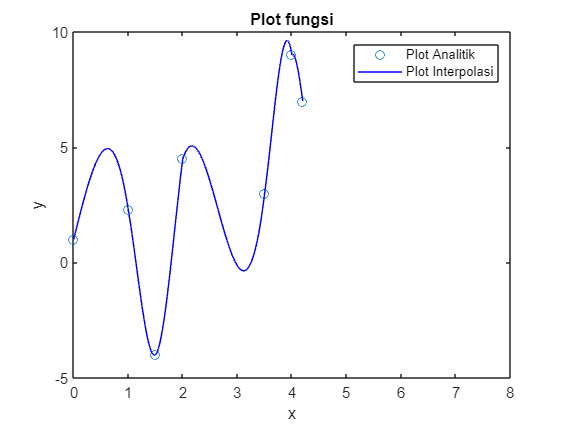

% Ketik jawaban Anda di bawah garis
% ===================================
s = [];
plot(x,y,"o")
legend("Plot Analitik")
hold on

for i = 1 : 6
    xplot = linspace(x(i),x(i+1),100);
    for j = 1: 100
        s(j) = a(i).*(xplot(j)-x(i)).^3+b(i).*(xplot(j)-x(i)).^2+c(i).*(xplot(j)-x(i))+d(i);
    end
    plot (linspace(x(i),x(i+1),100),s, color="blue")

end
title("Plot fungsi")
xlabel("x")
ylabel("y")

legend ("Plot Analitik","Plot Interpolasi")
xlim([0,8])
ylim([-5,10])
hold off

## Nomor 1F

Sekarang, jika fungsi-fungsi anda sudah tepat, lakukan interpolasi Natural Cubic Spline dengan $p\left(x\right)=e^{\sin \left(x\right)}$ pada selang $x=\left\lbrack -3,3\right\rbrack$ dan $\Delta x=0\ldotp 1$!

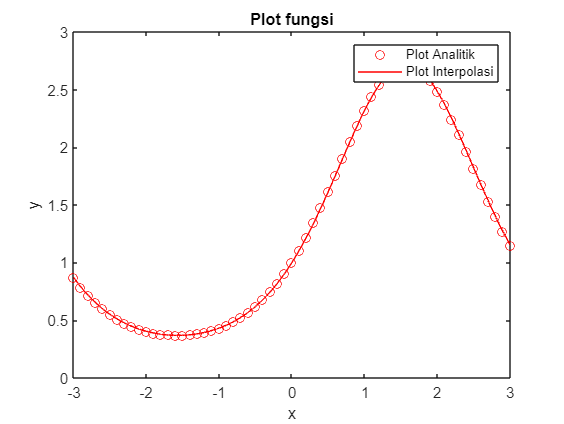

% Ketik jawaban anda di bawah garis
% =================================
x = linspace(-3, 3, 61);
y = exp(sin(x));
plot(x,y,"o", color = "red")
legend("Plot Analitik")
hold on

[h, b] = b_finder(x, y);
[a, c, d] = ncspline(h, b, y);

s = [];

for i = 1:length(x) - 1
    xplot = linspace(x(i), x(i + 1), 100);
    for j = 1:100
        s(j) = a(i) * (xplot(j) - x(i)).^3 + b(i) * (xplot(j) - x(i)).^2 + c(i) * (xplot(j) - x(i)) + d(i);
    end
    plot(linspace(x(i), x(i + 1), 100), s,color="red");
end
legend ("Plot Analitik","Plot Interpolasi")
hold off;


title('Plot fungsi');
xlabel('x');
ylabel('y');
